% Expand the Fourier series of a periodic function f(x) with period 2, 
% given in the interval (-1;1) by the equation f(x)=x^2.

clear;
syms x pi;
f(x)=x^2;
L=1;

a0=(2/L)*int(f(x),x,0,1)

$$a0 = \frac{2}{3}$$

% 2/3

syms m integer;
assume(m>=1)
a(m)=(2/L)*int(f(x)*cos(m*pi*x/L),x,0,1)

$$a(m) = \frac{2\,\left(m^{2}\,\pi^{2}\,\sin\left(\pi \,m\right)-2\,\sin\left(\pi \,m\right)+2\,\pi \,m\,\cos\left(\pi \,m\right)\right)}{m^{3}\,\pi^{3}}$$

% (2*(m^2*pi^2*sin(pi*m) - 2*sin(pi*m) + 2*m*pi*cos(pi*m)))/(m^3*pi^3)
%                =0             =0               =(-1)^m 
a(m)=subs(a(m),[sin(pi*m) cos(pi*m)],[0 (-1)^m])

$$a(m) = \frac{4\,{\left(-1\right)}^{m}}{m^{2}\,\pi^{2}}$$

% (4*(-1)^m)/(m^2*pi^2)
af(m)=a(m)*cos(m*pi*x/L)

$$af(m) = \frac{4\,{\left(-1\right)}^{m}\,\cos\left(\pi \,m\,x\right)}{m^{2}\,\pi^{2}}$$

% (4*(-1)^m*cos(pi*m*x))/(m^2*pi^2)

% f(x)-even => b(m)=0
b(m)=sym(0)

$$b(m) = 0$$

bf(m)=b(m)*sin(m*pi*x/L)

$$bf(m) = 0$$

% 0
abf(m)=af(m)+bf(m)

$$abf(m) = \frac{4\,{\left(-1\right)}^{m}\,\cos\left(\pi \,m\,x\right)}{m^{2}\,\pi^{2}}$$

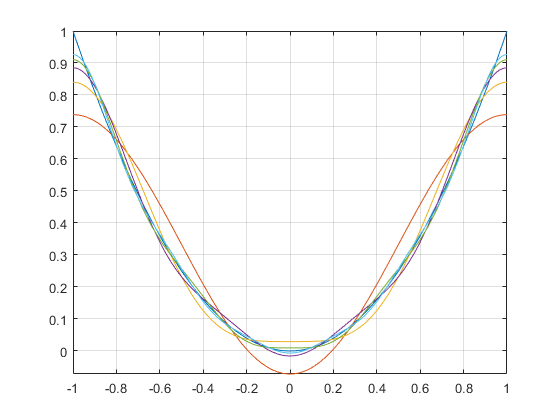

% (4*(-1)^m*cos(m*x))/(m^2*pi^2)

fplot(f(x),[-1 1]);
hold on;

f1=a0/2;
for m=1:5
    m1(m)=m;
    a1(m)=a(m);
    b1(m)=b(m);
    abf1(m)=abf(m);
    f1=f1+abf(m);
    fplot(f1,[-1 1]);
    grid on
end
hold off


a0/2

$$ans = \frac{1}{3}$$

% 1/3
ft=[m1;a1;b1;abf1];
ft'

$$ans = \left(\begin{array}{cccc} 1 & -\frac{4}{\pi^{2}} & 0 & -\frac{4\,\cos\left(\pi \,x\right)}{\pi^{2}}\\ 2 & \frac{1}{\pi^{2}} & 0 & \frac{\cos\left(2\,\pi \,x\right)}{\pi^{2}}\\ 3 & -\frac{4}{9\,\pi^{2}} & 0 & -\frac{4\,\cos\left(3\,\pi \,x\right)}{9\,\pi^{2}}\\ 4 & \frac{1}{4\,\pi^{2}} & 0 & \frac{\cos\left(4\,\pi \,x\right)}{4\,\pi^{2}}\\ 5 & -\frac{4}{25\,\pi^{2}} & 0 & -\frac{4\,\cos\left(5\,\pi \,x\right)}{25\,\pi^{2}} \end{array}\right)$$

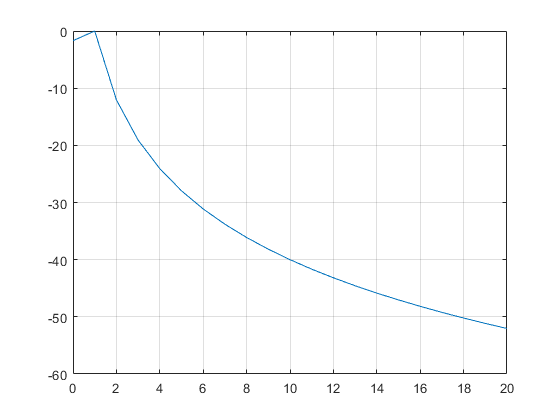

% [ 1,      -4/pi^2, 0,        -(4*cos(pi*x))/pi^2]
% [ 2,       1/pi^2, 0,           cos(2*pi*x)/pi^2]
% [ 3,  -4/(9*pi^2), 0,  -(4*cos(3*pi*x))/(9*pi^2)]
% [ 4,   1/(4*pi^2), 0,       cos(4*pi*x)/(4*pi^2)]
% [ 5, -4/(25*pi^2), 0, -(4*cos(5*pi*x))/(25*pi^2)] 

x=0:20;
y(1)=a0/2;
for m=1:20
    y(m+1)=a(m)+1i*b(m);
end
yd=20*log10(abs(y)/abs(y(2)));

plot(x,yd)
grid on;